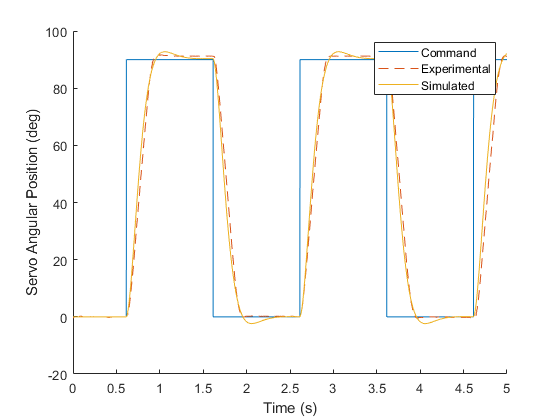

close all;
clc;
clear;

out = sim('servo_harness');

t = out.ScopeData.time;
experimental = out.ScopeData.signals(1).values;
simulated = out.ScopeData.signals(2).values;
temp = out.ScopeData.signals(3).values(1,1,:);
command = squeeze(temp(1,1,:));

figure(1)
hold on;

plot(t, command);
plot(t, experimental, "--");
plot(t, simulated);
xlabel("Time (s)")
ylabel("Servo Angular Position (deg)");
legend("Command", "Experimental", "Simulated")